## **Relatório Matemática Computacional**

close all
clear all
f = @(x,a) ((x-1).^2).*(exp(x-1)-1)+a;
d1f = @(x) exp(-1)*(x-1).*((x+1).*exp(x)-2*exp(1));
d2f = @(x) (x.^2+2.*x-1).*exp(x-1)-2;
J = [0,3/2];

### **a)**

a = 1/10;
I = [0,0.7];

Para provar a convergência do método de Newton as condições do critério 1 têm de ser verificadas.

Sendo f uma função C^2

1) f(a)f(b)<0 (existência de raíz)

f(I(1),a).*f(I(2),a) < 0

ans = logical
   1


2) f'(x)!=0 para qualquer x pertencente ao intervalo I (unicidade da raíz)

d1f(I(1)).*d1f(I(2)) > 0

ans = logical
   1


(x.^2+2.*x-1).*exp(x-1)-2 > 0 para qualquer x pertencente ao intervalo I

3) f''(x)>=0 ou f''(x)<=0 para qualquer x pertencente ao intervalo I (não muda o sentido da concavidade)

(x.^2+2.*x-1).*exp(x-1)-2 < 0 para qualquer x pertencente ao intervalo I

4)

abs(f(I(1),a))./abs(d1f(I(1))) < I(2)-I(1)

ans = logical
   1


abs(f(I(2),a))./abs(d1f(I(2))) < I(2)-I(1)

ans = logical
   1


### b)

format LongE
r = real_zero(1/10,0.3);
fprintf('O zero real é: %i',r)

O zero real é: 4.970199e-01

[rbar,k] = newton_method(a,0.3,25, 10.^(-2));
fprintf("A raíz é: %i\n",rbar(end))

A raíz é: 4.970077e-01


fprintf("A iteração é: %i",k)

A iteração é: 3

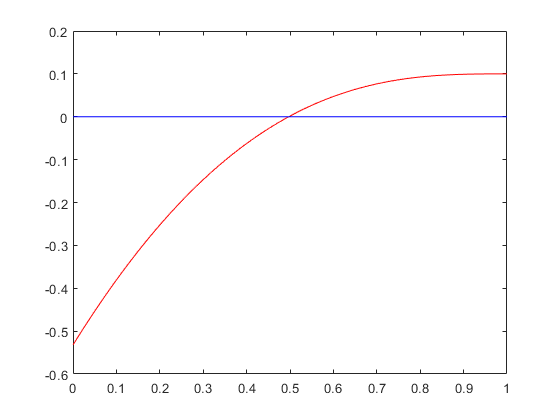


%Representação gráfica
s=0:0.01:1;
plot(s,((s-1).^2).*(exp(s-1)-1)+a,"Color",'r')
hold on
yy=zeros(1,length(s));
plot(s,yy,'Color','b')
hold off

### c)

M=41;
a_i = linspace(-1/10,1/10,M);
ga = [];
kga = [];
for i = 1:1:numberofelements(a_i)
    [rbar,k] = newton_method(a_i(i),0.9,25,10.^(-7));
    ga(end+1) = rbar(end);
    kga(end+1) = k;
end

#### i)

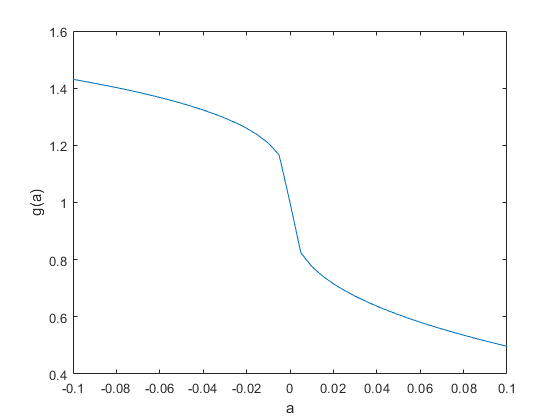

plot(a_i,ga)
xlabel('a')
ylabel('g(a)')

#### ii)

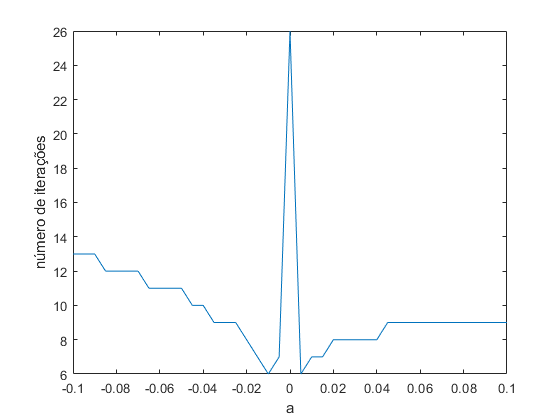

plot(a_i,kga)

xlabel('a')
ylabel('número de iterações')

fazer tabela

format short
[~,k1] = newton_method(-0.1,0.9,25,10.^(-7));
[~,k2] = newton_method(-0.05,0.9,25,10.^(-7));
[~,k3] = newton_method(0,0.9,25,10.^(-7));
[~,k4] = newton_method(0.05,0.9,25,10.^(-7));
[~,k5] = newton_method(0.1,0.9,25,10.^(-7));
[-0.01 -0.05 0 0.05 0.01; k1 k2 k3 k4 k5]

ans =    -0.0100   -0.0500         0    0.0500    0.0100
   13.0000   11.0000   26.0000    9.0000    9.0000


### d)

Através da visualização gráfica verificamos que para um determinado *a* a função f(a) tem um zero múltiplo.

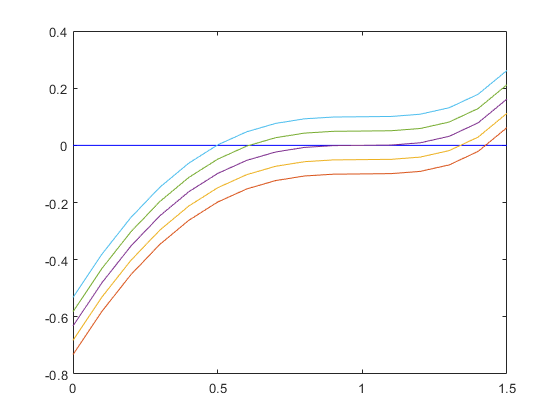

x = J(1):0.1:J(2);
yy=zeros(1,length(x));
plot(x,yy,'Color','b')
hold on
for  i = -1/10:0.05:1/10
    plot(x,f(x,i))
    %pause(0.5)
end
hold off

O zero múltiplo dá-se no caso em que no zero da função a sua respetiva derivada também é zero. Isso acontece quando a = 0 

Pelo gráfico apresentado na alínea anterior percebemos que o Método de Newton não funciona tão bem para estes casos uma vez que se destaca um pico no número de iterações em a = 0.

### e)

Caso a = 1/10:

%format longE
a = 1/10;

a = 0.1000

r = real_zero(a,0.3);
[res1,~] = newton_method(a,0.3,k, 10.^(-7));
[res2,~] = newton_method(a,0.3,k-1, 10.^(-7));
[res3,~] = newton_method(a,0.3,k-1, 10.^(-7));

Caso a = 0, dada uma iteração x0

a = 0;
x0 = 0.3;
r = real_zero(0,x0);
[res1,~] = newton_method(0,x0,1, 10.^(-7));
[res2,~] = newton_method(0,x0,2, 10.^(-7));
[res3,~] = newton_method(0,x0,3, 10.^(-7));

res = [];
k = 3;
for i = 1:1:k
    res 
end

%iteradas
x0

x0 = 0.3000

x1 = res1(end)

x1 = 0.5602

x2 = res2(end)

x2 = 0.7175

x3 = res3(end)

x3 = 0.8161


%erros
e0 = r-x0

e0 = 0.7000

e1 = r-x1

e1 = 0.4398

e2 = r-x2

e2 = 0.2825

e3 = r-x3

e3 = 0.1839

Exprimentar convergência linear:

abs(e0)/abs(e1).^1

ans = 1.5915

abs(e1)/abs(e2).^1

ans = 1.5567

abs(e2)/abs(e3).^1

ans = 1.5361

Exprimentar convergência quadrática:

abs(e1)/(abs(e2)).^2

ans = 5.5100

Exprimentar convergência superior

abs(e1)/(abs(e2)).^3

ans = 19.5025

*?????? não converge para valor nenhum com p=1, 2, 3*

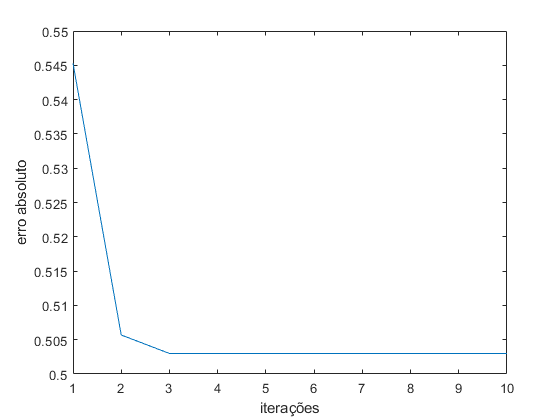

%Desenhar gráfico do erro absoluto em função das iterações
x = 1:1:10;
y = [];
n=0;
for i = 1:1:10
    [resultado,~] = newton_method(a,0.3,i,10.^(-7));
    y(1+n)= abs(r-resultado(end));
    n=n+1;
end
plot(x,y)
xlabel('iterações')
ylabel('erro absoluto')

### f)

*Preciso ter um resultado em e) para dizer alguma coisa*

### Definição de Funções

%Função do Método de Newton
function [rbar,k] = newton_method(a,x0,nmax,epsilon)
nmax = nmax+1;
f = @(x,a) ((x-1).^2).*(exp(x-1)-1)+a;
d1f = @(x) exp(-1)*(x-1).*((x+1).*exp(x)-2*exp(1));
x=[x0];
k=1;
while k<nmax
    x(k+1)= x(k)-f(x(k),a)./d1f(x(k));
    if abs(x(k+1)-x(k)) < epsilon;
        break
    end
    k=k+1;
end
rbar = x;
end

%Função do zero real
function [r] = real_zero(a,x0)
g = @(x)((x-1).^2).*(exp(x-1)-1)+a;
r = fzero(g,x0);
end